# boas praticas

clear all
close all
clc


## leitura dados

T = readtable('SIRpd.csv');   % lendo dados csv e transformando em tabela
T = table2array(T);            % transformando tabela em array
%% Indexando cada parte da tabela para separar S R e I
Sd = T(:,1);                   
Id = T(:,2);
Rd = T(:,3);

## gerando numeros aleatórios para somar com os dados do csv

Sdn = mean(Sd)/10 + 20.*randn(1000,1);

Idn = mean(Id)/5 + 10.*randn(1000,1);

Rdn = mean(Rd)/10 + 20.*randn(1000,1); 

## somando números aleatórios com os dados do csv para gerar erro gaussiano


Sd = Sd + Sdn;
Id = Id + Idn;
Rd = Rd + Rdn;

## Chamando modelo SIR

% Tamanho da populção - N
N = 500;

% Valores iniciais 
i0 = 1;
r0 = 0;
s0 = N - i0;

% Vetor de condições iniciais

y0 = [s0 i0 r0];

% Beta -  taxa de contato,
% r - taxa média de recuperação (in 1/dia).

theta0 = [1e-4,1e-2]; % valores iniciais
beta = theta0(1);
r = theta0(2);
% Definição do conjunto de equações diferencias não lineares que formam o modelo.

t = linspace(0,1000,1000);
mdl = 'SimulacaoSIR';
load_system(mdl)
cs = getActiveConfigSet(mdl);
mdl_cs = cs.copy;
set_param(mdl_cs,'AbsTol','1e-5',...
         'SaveState','on','StateSaveName','xoutNew',...
         'SaveOutput','on','OutputSaveName','youtNew');
simOut = sim(mdl, mdl_cs);

## Visualizando a evolução da Epidemia - S(t), I(t) e R(t) pelo modelo e pelos dados

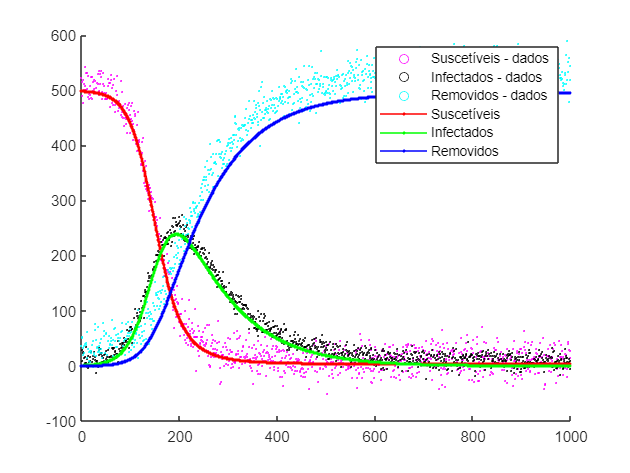

S = simOut.logsout{1}.Values.Data;
I = simOut.logsout{2}.Values.Data;
R = simOut.logsout{3}.Values.Data;

t = linspace(0,length(S),length(S));
td = linspace(0,length(Sd), length(Sd));

figure(1)

scatter(td,Sd, 0.8, 'magenta')
hold on;
scatter(td,Id, 0.8, 'black')
scatter(td,Rd, 0.8, 'cyan')
plot(t, S, marker='.', color='r')
plot(t, I, marker='.', color='g')
plot(t, R, marker='.', color='b')


legend('Suscetíveis - dados', 'Infectados - dados', 'Removidos - dados', 'Suscetíveis', 'Infectados', 'Removidos')
xlabel = ('Dias');
ylabel = ('Indivíduos');
hold off;